Last inn Iris data

clear;
x1 = load('IrisData/class_1','-ascii'); % Iris-setosa 50x4
x2 = load('IrisData/class_2','-ascii'); % Iris-versicolor 50x4
x3 = load('IrisData/class_3','-ascii'); % Iris-virginica 50x4

Visualisering av Iris data

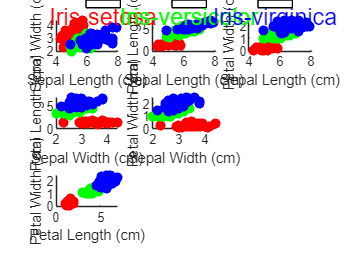

dim_labels = {'Sepal Length (cm)', 'Sepal Width (cm)', 'Petal Length (cm)', 'Petal Width (cm)'};
figure;
annotation('textbox', [0.25, 0.97, 0.1, 0.03], 'String', '• Iris-setosa', 'FontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'r');
annotation('textbox', [0.5, 0.97, 0.1, 0.03], 'String', '• Iris-versicolor', 'FontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'g');
annotation('textbox', [0.75, 0.97, 0.1, 0.03], 'String', '• Iris-virginica', 'FontSize', 14, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'b');
for i = 1:3
    for j = i+1:4
        subplot(3, 3, (i-1)*3 + j-i);
        scatter(x1(:,i), x1(:,j), 'r', 'filled');
        hold on;
        scatter(x2(:,i), x2(:,j), 'g', 'filled');
        scatter(x3(:,i), x3(:,j), 'b', 'filled');
        xlabel(dim_labels{i});
        ylabel(dim_labels{j});
    end
end
hold off;

Oppgave 1

a) 30 første samplene til trening + 20 siste til testing

x1_train=x1(1:30,:); x1_test=x1(31:50,:);
x2_train=x2(1:30,:); x2_test=x2(31:50,:);
x3_train=x3(1:30,:); x3_test=x3(31:50,:);

b) + c)

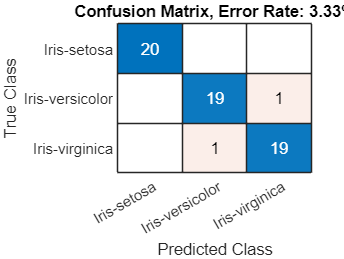

X_train = [x1_train; x2_train; x3_train];
Y_train = [ones(size(x1_train, 1), 1); ...
           2 * ones(size(x2_train, 1), 1); ...
           3 * ones(size(x3_train, 1), 1)];

IrisModel = fitcdiscr(X_train, Y_train);

X_test = [x1_test; x2_test; x3_test];
Y_test_true = [ones(size(x1_test, 1), 1); ...
               2 * ones(size(x2_test, 1), 1); ...
               3 * ones(size(x3_test, 1), 1)];


Y_test_pred = predict(IrisModel, X_test);

confusion_matrix = confusionmat(Y_test_true, Y_test_pred);
error_rate = 1 - sum(diag(confusion_matrix)) / sum(confusion_matrix(:));

class_labels = {'Iris-setosa', 'Iris-versicolor', 'Iris-virginica'};
figure;
confusionchart(confusion_matrix, class_labels);
title(['Confusion Matrix, Error Rate: ', num2str(round(error_rate * 100,2)), '%']);

d) 20 første samplene til testing + 30 siste til trening

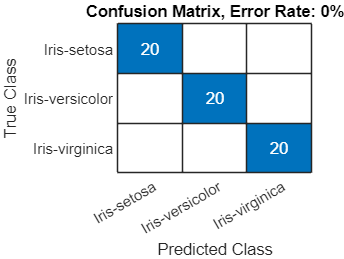

x1_train2 = x1(21:50, :); x1_test2 = x1(1:20, :);
x2_train2 = x2(21:50, :); x2_test2 = x2(1:20, :);
x3_train2 = x3(21:50, :); x3_test2 = x3(1:20, :);

X_train2 = [x1_train2; x2_train2; x3_train2];
Y_train2 = [ones(size(x1_train2, 1), 1); ...
           2 * ones(size(x2_train2, 1), 1); ...
           3 * ones(size(x3_train2, 1), 1)];

IrisModel = fitcdiscr(X_train2, Y_train2);

X_test2 = [x1_test2; x2_test2; x3_test2];
Y_test_true2 = [ones(size(x1_test2, 1), 1); ...
               2 * ones(size(x2_test2, 1), 1); ...
               3 * ones(size(x3_test2, 1), 1)];


Y_test_pred2 = predict(IrisModel, X_test2);

confusion_matrix2 = confusionmat(Y_test_true2, Y_test_pred2);
error_rate2 = 1 - sum(diag(confusion_matrix2)) / sum(confusion_matrix2(:));

figure;
confusionchart(confusion_matrix2, class_labels);
title(['Confusion Matrix, Error Rate: ', num2str(round(error_rate2 * 100, 2)), '%']);

Oppgave 2

a)